# Progettino

## Esercizio 2


$$G(s) = \frac{1}{s(s + 4)^3}$$


Richieste:

- errore massimo del 5% rispetto ad un riferimento a rampa con pendenza unitaria

- sovraelongazione percentuale massima pari al 20% e tempo di salita minore di 3 secondi

#### Primo punto 

s = tf('s');
Gs = 1/(s*(s + 4)^3);
pole(Gs)

ans =    0.0000 + 0.0000i
  -4.0000 + 0.0000i
  -4.0000 + 0.0000i
  -4.0000 - 0.0000i


Prima di iniziare bisogna inserire il ricostruttore H(s) del modello dell'impianto: 

$H(s) =  \frac{T_s}{(1 + \frac{T_s}{2} \cdot s)}$ , scegliamo $T_s$= $\frac{2}{50}$

%introduciamo il tempo di campionamento
Ts = 2/50;
%mettiamo il ricostruttore 
Hs = Ts/(1 + (Ts/2)*s);
Ps = (1/Ts)*Hs*Gs

Ps =
 
                          1
  --------------------------------------------------
  0.02 s^5 + 1.24 s^4 + 12.96 s^3 + 49.28 s^2 + 64 s
 
Continuous-time transfer function.
Model Properties


K = 1280;
Cs = K;
%Ls = minreal(Cs * Gs)
Ls = minreal(Cs * Ps)

Ls =
 
                    64000
  ------------------------------------------
  s^5 + 62 s^4 + 648 s^3 + 2464 s^2 + 3200 s
 
Continuous-time transfer function.
Model Properties


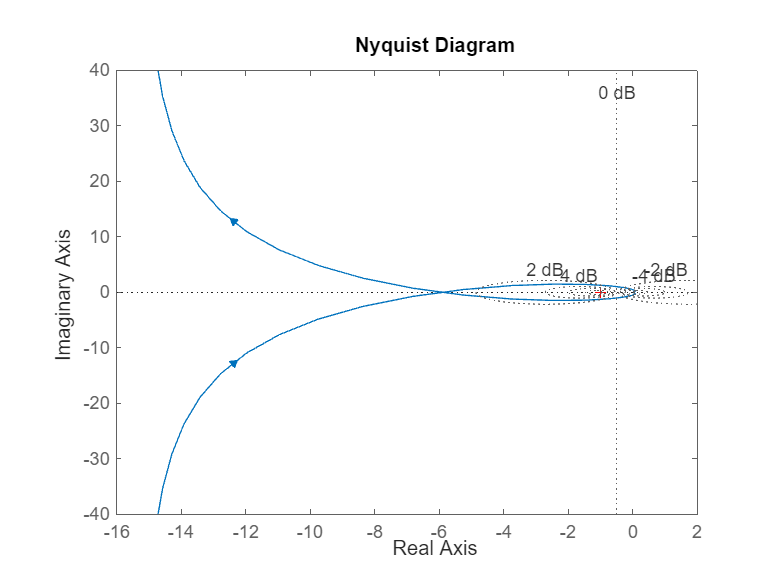

nyquist(Ls)
grid

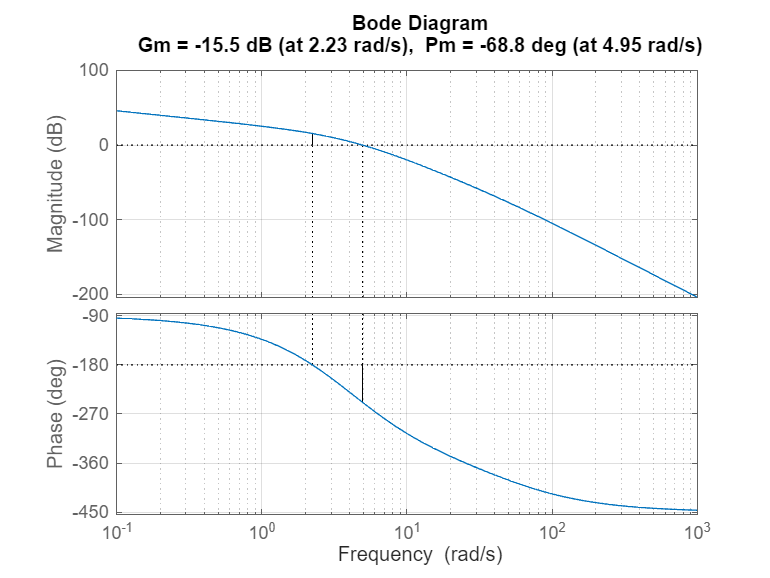

margin(Ls)
grid

Come possiamo notare il sistema è instabile, e inoltre non rispetta il criterio di Bode, si deduce che non stiamo lavorando con un problema semplice, dobbiamo fare in modo di ovviare a questa cosa, vediamo cosa si può fare attraverso le specifiche statiche

Il primo punto lo abbiamo soddisfatto, quindi le specifiche di precisione statica, ora andiamo a svolgere il secondo punto riguardante le specifiche di precisione dinamica.

#### Secondo punto 

Per il secondo punto dobbiamo calcolare il delta che poi mi permetterà di trovare il resto


$$\delta = \frac{1}{\sqrt{1 + (\frac{\pi}{log(S)})^2)}$$


dove S equivale alla sovraelongazione che nel nostro caso andiamo a mettere a 0,2

S = 0.2;
delta = 1/sqrt(1 + (pi/log(S))^2) %fattore di smorzamento desiderato

delta = 0.4559

%calcoliamo a questo punto il margine di fase
phi_m = 100*delta

phi_m = 45.5950

ora con la specifica relariva al tempo di salita andiamo a calcolare il valore che dovrebbe avere il lower bound della banda passante

time_rising = 3; 
omega_b = 0.8 * pi / time_rising

omega_b = 0.8378

%la scelta di omega_c deve essere in modo che omega_c risulti > omega_b
omega_c = 0.88;
[M, phi] = bode(Ls, omega_c)

M = 21.1685

phi = -128.2306

phi_corrente = 180 - abs(phi)

phi_corrente = 51.7694

In questo caso abbiamo che phi_corrente > ohi_m e che M > 1 dunque ci troviamo nel caso della progettazione di una rete attenuatrice

Si deve quinfi sviluppare un controllore del tipo $C_{lag} = \frac{1 + \alpha T s}{1 + T s}$, per farlo dobbiamo andare a trovare i parametri $\alpha$, $T$

m = 1/M

m = 0.0472

theta = -1.2

theta = -1.2000

alpha = m*(cos(deg2rad(theta))-m)/(1-m*cos(deg2rad(theta)))

alpha = 0.0472

T = (1/omega_c)*sqrt((1-m^2)/(m^2-alpha^2))

T = 1.0944e+03

Clag = (1+s*alpha*T)/(1+s*T)

Clag =
 
  51.69 s + 1
  -----------
  1094 s + 1
 
Continuous-time transfer function.
Model Properties


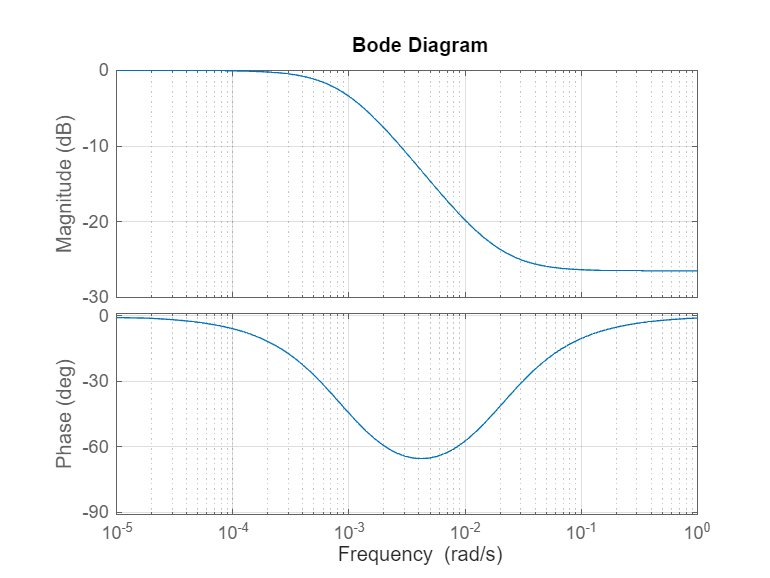

figure
bode(Clag)
grid

Ora calcoliamo il nostro sistema a ciclo chiuso 

Ls = Clag * Ls

Ls =
 
                               3.308e06 s + 64000
  -----------------------------------------------------------------------------
  1094 s^6 + 6.785e04 s^5 + 7.092e05 s^4 + 2.697e06 s^3 + 3.504e06 s^2 + 3200 s
 
Continuous-time transfer function.
Model Properties


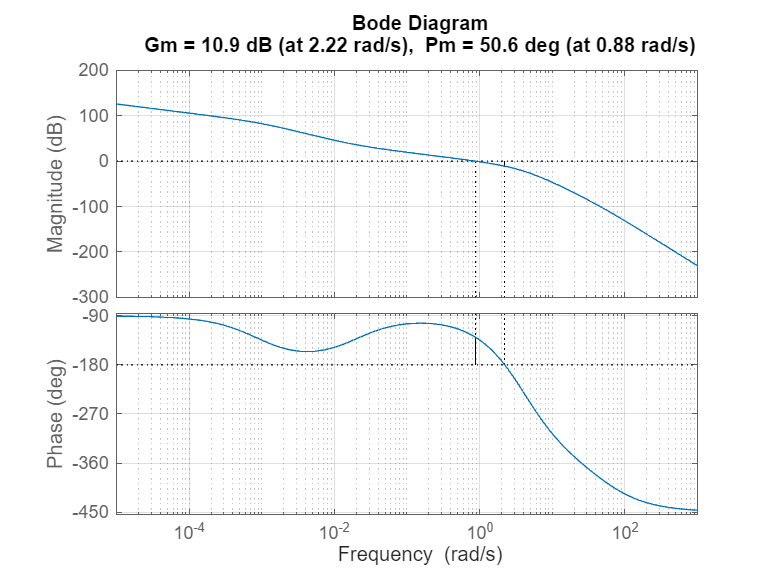

margin(Ls)
grid

Fs = minreal(feedback(Ls,1))

Fs =
 
                          3023 s + 58.48
  ---------------------------------------------------------------
  s^6 + 62 s^5 + 648.1 s^4 + 2465 s^3 + 3202 s^2 + 3026 s + 58.48
 
Continuous-time transfer function.
Model Properties


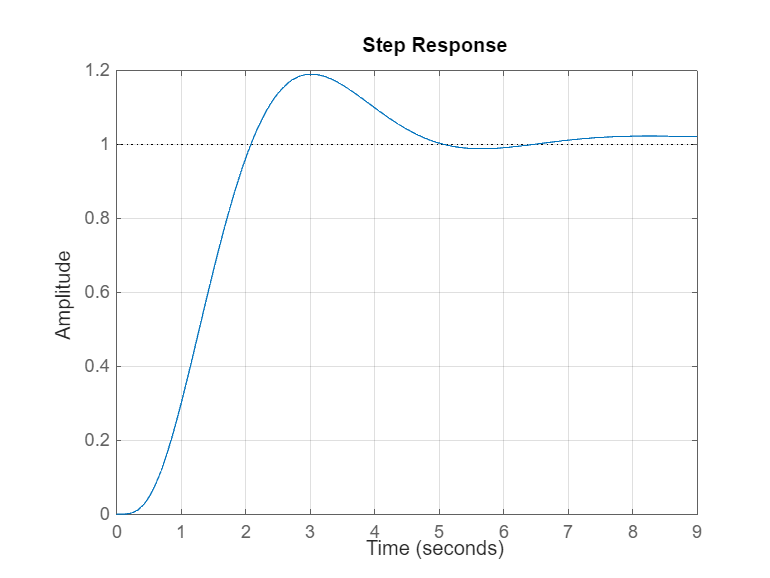

step(Fs)
grid

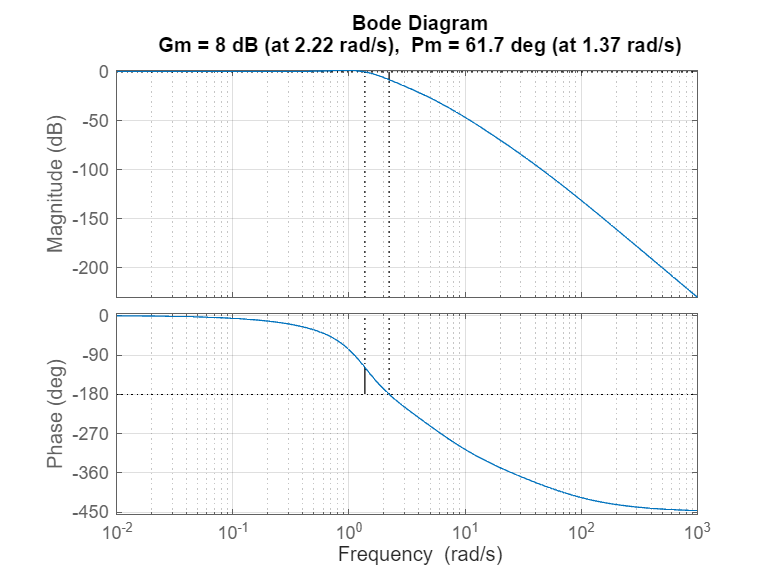

margin(Fs)
grid

stepinfo(Fs)

ans = struct with fields:
         RiseTime: 1.2297
    TransientTime: 9.1515
     SettlingTime: 9.1515
      SettlingMin: 0.9019
      SettlingMax: 1.1899
        Overshoot: 18.9862
       Undershoot: 0
             Peak: 1.1899
         PeakTime: 3.0239


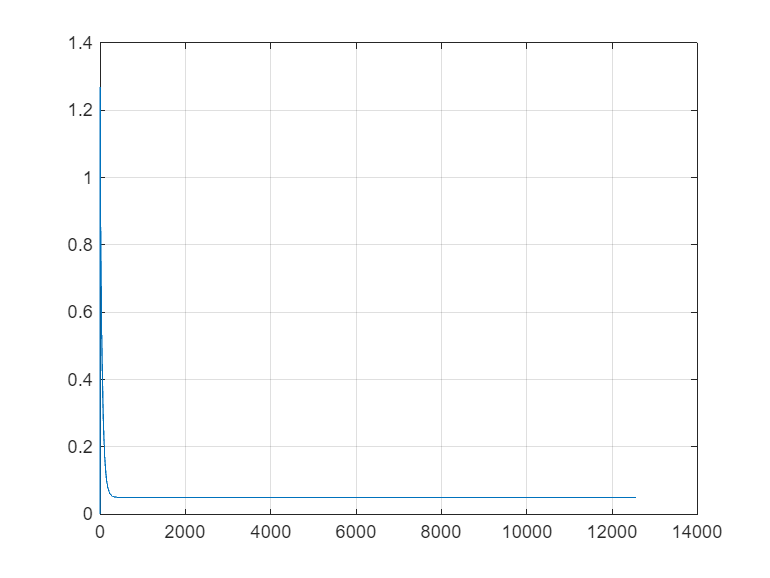

[y,t] = step((1/s)*Fs); %faccio il gradino di Fs * 1/s
r = t;
plot(t, r - y)
grid

Anche le specifiche sulla precisione dinamica sono state rispettate

A questo punto dobbiamo discretizzare e lo facciamo distinguendo i tre metodi: 

- Eulero in avanti

- Eulero all'indietro

- Tustin

[numeratore_ps, denominatore_ps] = tfdata(Gs, 'v');
Cs = Cs * Clag

Cs =
 
  6.616e04 s + 1280
  -----------------
     1094 s + 1
 
Continuous-time transfer function.
Model Properties


[numeratore_cs, denominatore_cs] = tfdata(Cs, 'v');

%eulero indietro
z = tf('z');
s = (z - 1)/(z*Ts)

s =
 
  z - 1
  ------
  0.04 z
 
Sample time: unspecified
Discrete-time transfer function.
Model Properties


Cs_eulero_indietro = minreal((6.616e04*s + 1280)/(1094*s + 1))

Cs_eulero_indietro =
 
  60.52 z - 60.47
  ---------------
       z - 1
 
Sample time: unspecified
Discrete-time transfer function.
Model Properties


[numeratore_eulero_indietro, denominatore_eulero_indietro] = tfdata(Cs_eulero_indietro, 'v');

%eulero in avanti 
s = (z - 1)/(Ts)

s =
 
  z - 1
  -----
  0.04
 
Sample time: unspecified
Discrete-time transfer function.
Model Properties


Cs_eulero_avanti = minreal((6.616e04*s + 1280)/(1094*s + 1))

Cs_eulero_avanti =
 
  60.48 z - 60.43
  ---------------
       z - 1
 
Sample time: unspecified
Discrete-time transfer function.
Model Properties


[numeratore_eulero_avanti, denominatore_eulero_avanti] = tfdata(Cs_eulero_avanti, 'v');

%tustin
Cs_tustin = c2d(Cs,Ts,'tustin')

Cs_tustin =
 
  60.47 z - 60.43
  ---------------
       z - 1
 
Sample time: 0.04 seconds
Discrete-time transfer function.
Model Properties


[numeratore_tustin, denominatore_tustin] = tfdata(Cs_tustin, 'v');
%open('simulink_progetto.slx')